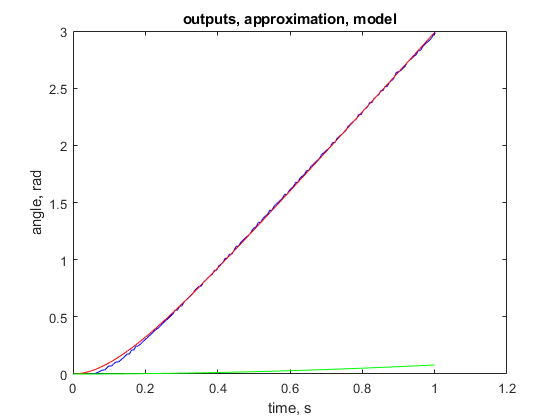

files = ["data20", "data-20", "data40", "data-40", "data60", "data-60", "data80", "data-80", "data100", "data-100"]; %
voltages = [20, -20, 40, -40, 60, -60, 80, -80, 100, -100]; %
k_all = [];
Tm_all = [];

    data = readmatrix(files(1));
    time=data(:,1);
    U = voltages(1);

    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    
    title("outputs, approximation, model")
ylabel("angle, rad")
xlabel("time, s")

    figure(1)
    plot(time,angle, 'blue');  
    hold on
    % approximation - let's take
    lol0 = [0.1 ; 0.06];
    % given voltage in percents
    U_pr = 100;
    % 0(t) = ...
    func = @(lol, time) U_pr*lol(1)*(time - lol(2)*(1 - exp(-time/lol(2))));
    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,lol0,time,angle);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


    k = solver(1)

k = 0.0348

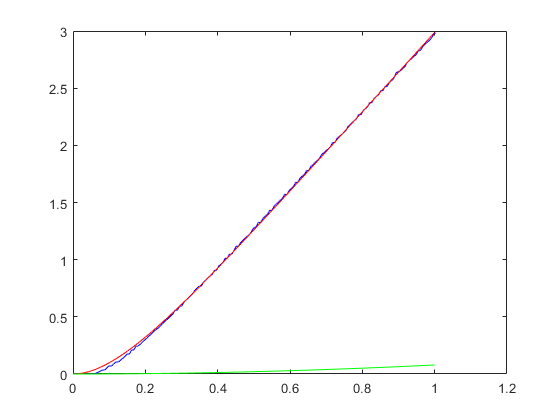

    k_special =  28.6987;
    Tm = solver(2);
  
    time_apr = 0:0.01:1;
    theta = U_pr*k*(time_apr - Tm*(1 - exp(-time_apr/Tm)));
    plot(time_apr,theta, 'red');
    hold on
    plot(out.theta.Time, out.theta.Data, 'green');
    hold off

Итог: чтобы запустить модель корректно, надо для каждого случая заходить в модель и вручную проставлять значения: напряжение, k, Tm.

Пример: